# ME 322 Exercise 1 Report - Introduction to Numerical Simulation and Review of Transfer Functions

**Written by:        **Caiden Bonney - Cal Poly Mechanical Engineering Undergraduate

**Created:**            4/7/2025

**Modified:           **4/13/2025

**Background:    **

*Summarize in a few sentences what you are doing in this lab. *

This script is a lab report for ME322. This lab exercise is split into two parts, Exercise 1A and Exercise 1B. Exercise 1A simulates the response of a second-order linear ordinary differential equation (ODE) of a mass-spring-damper system driven by a step input forcing function using "ode45" in MATLAB to simulate the mass's displacement, $x_m \left(t\right)$, and velocity, $v_m \left(t\right)$. These are then plotted against time in two plots, $x_m \left(t\right)$ vs $t$ and $v_m \left(t\right)$ vs $t$. In Exercise 1B the transfer function for the mass-spring-damper's ODE from Exercise 1A is calculated symbolically. Using the same system parameters as Exercise 1A with zero intial conditions and a sinusoidal forcing function instead of a step input the displacement is calculated in Simulink using the transfer function. Substituting for a steady-state sinusoidal response the complex transfer function is calculated and used to find the magnitude ratio and the phase shift of the system which are then used to adjust the input sinusoidal forcing function to compare to the results calculated in Simulink. 

**Required Files:**

- ME322_Exercise_1_Matlab.mlx

- ME322_Exercise_1_Simulink.slx

- snapshotModel.m

**References:**

        [1]  ME322_2254_Lab_Manual.pdf

        [2]  ME318_formula_sheet.pdf

## Problem Statement

*This section must focus on the problem statement and an overview of the solution method. Describe any new methods or concepts that you implemented and why they were appropriate to use. It is encouraged to reuse figures and equations from the lab manual within the report as long as they are properly cited.*

*Include schematics, helpful information regarding the assignment that help orient the reader in what you are working on. *

### Exercise 1A: Introduction to Numerical Simulation

Consider Figure 1 which depicts a parallel mass-spring-damper system consisting of a mass, $m$, spring, $k$, and damper, $b$. The displacement, $x_m$, and velocity, $v_m$, are also labeled in Figure 1 in which positive is to the right. Assume that there is no sliding friction acting on the mass and that due to this gravity has no effect on the mass. Create a simulation describing the displacement and velocity of the system over the period of $0\le t\le 2$ using "ode45" and the function "MBK_state_eqns" defined in the Lab Manual [1].

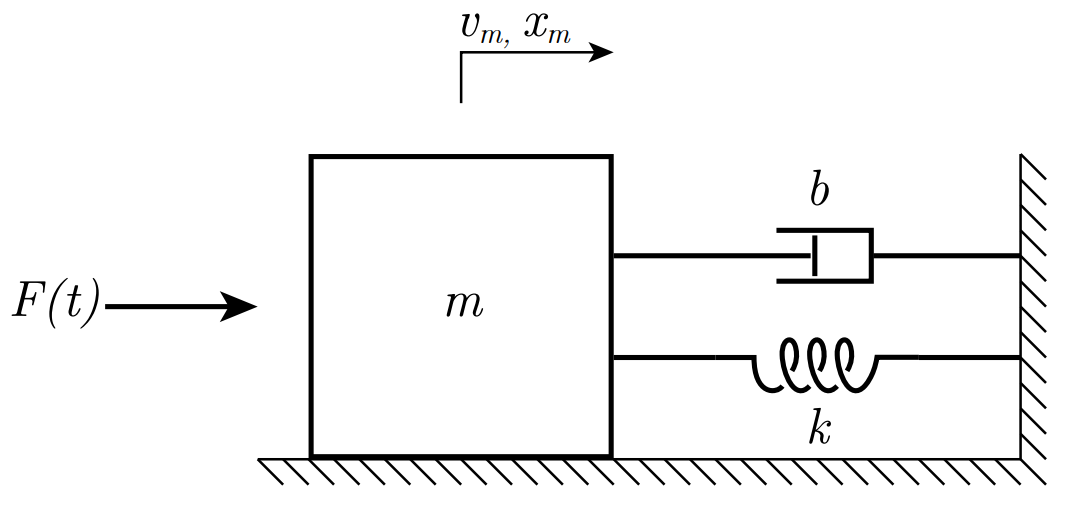

**Figure 1: **Parallel mass-spring-damper [1].

The simulation shall assume the systems initial conditions to be the values noted in Figure 2 and the "MBK_state_eqns" function must be updated to include these inital conditions and system values.

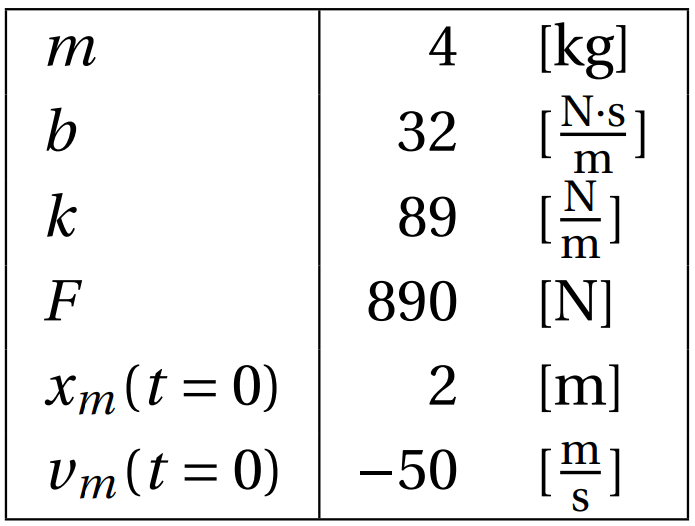

**Figure 2: **Parallel mass-spring-damper phyisical system parameters [1].

The force, $F$, is a forcing function that begins at time > 0 and remains a constant value of $F=890\;\left\lbrack N\right\rbrack$ which can be modeled as a step-function that begins at $t=0\;\left\lbrack s\right\rbrack$. The first three inital conditions noted in Figure 2, $m$, $k$, and $b$ are to be used for the simulation of the system in Exercise 1B as well. 

Create a figure consisting of two subplots, the Displacement, $x_m$ versus Time, $t$ and Velocity, $v_m$ versus Time, $t$ from $0\le t\le 2$. 

### Exercise 1B: Review of Transfer Functions

Simulate the previous system depicted in Figure 1 using Simulink with the transfer function representation of the system. The forcing function will be a sinusoidal input $F\left(t\right)=377\sin \left(2t\right)$ and the inital conditions $x_m \left(0\right)=v_m \left(0\right)=0$. Hand calculaute the transfer function for the differential equation, 

${\textrm{ma}}_m +bv_m +kx_m =F\left(t\right)\;\;;\;t\ge 0$   [1].

Symbolically hand calculate the transfer function and numerically calculate the complex transfer function for a steady-state sinusoidal response in form of $a+\textrm{bj}$ in MATLAB.

Using these values, calculate the magnitude ratio, $M\left(\omega \right)$, and the phase shift, $\phi \left(\omega \right)$. Plot the input sinusoid and output sinusoid to confirm that the magnitude ratio, $M\left(\omega \right)$, and the phase shift, $\phi \left(\omega \right)$ previously calculated align with the Simulink calculations. 

## Hand Calculations

*Submitted lab reports should include neat mathematical derivations and diagrams where appropriate. Properly scanned hand calculations are acceptable, although live scripts in MATLAB™ can include formatted mathematical equations if you prefer to enter them that way. All hand calculations should be written neatly and include a single equation per line as you should be doing for your homework already. You can choose to place all your hand calculations together or you may distribute them throughout the report near pertinent sections of code. *

### Exercise 1A

To fill out the missing components of the function "MBK_state_eqns" a vector of the state space system is required in the form $\dot{x} =f\left(x,u,t\right)$.

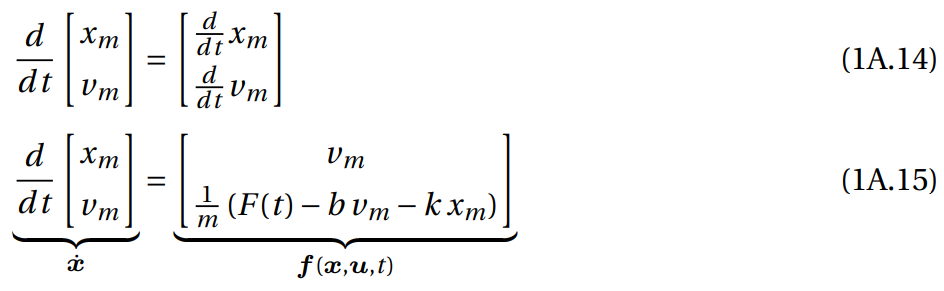

**Figure 3:** Derivative of state vector used by ode45 calculated in the Lab Manual [1].

The intial state vector is created in the Analysis - Exercise 1A section below. The implementation of the vector calculated in Figure 3 is shown below in the Functions section. 

### Exercise 1B

Calculating the transfer function, $G\left(s\right)$, for the second-order linear ordinary differential equation given in the Problem Statement section.


$$ma_m +bv_m +kx_m =F\left(t\right)\;\;;\;t\ge 0$$



$$m{\ddot{x} }_m +b{\dot{x} }_m +kx_m =F\left(t\right)\;$$



$$L\left\lbrace m{\ddot{x} }_m +b{\dot{x} }_m +kx_m \right\rbrace =L\left\lbrace F\left(t\right)\right\rbrace \;$$



$$ms^2 x_m \left(s\right)+\textrm{bs}x_m \left(s\right)+kx_m \left(s\right)=F\left(s\right)\;$$



$$\left(ms^2 +\textrm{bs}+k\right)x_m \left(s\right)=F\left(s\right)$$



$$G\left(s\right)=\frac{x_m \left(s\right)}{F\left(s\right)}=\frac{1}{ms^2 +\textrm{bs}+k}$$


Evaluating this transfer function for a steady-state sinusoidal response in which $s=\omega j$


$$G\left(\omega \right)=\frac{1}{k-m\omega^2 +b\omega j}$$


The numerical evaluation of this transfer function to calculate $a+\textrm{bj}$ is done in the Analysis - Exercise 1B section. The magnitude ratio and phase angle are also calculated using MATLAB's functions in this section.

Hand calculating the magnitude ratio and phase shift based on the formula:

$G\left(\omega \right)=\frac{x+\textrm{yj}}{u+\textrm{vj}}$, $M\left(\omega \right)=\frac{\sqrt{x^2 +y^2 }}{\sqrt{u^2 +v^2 }}$, $\phi \left(\omega \right)=\tan^{-1} \left(\frac{y}{x}\right)-\tan^{-1} \left(\frac{v}{u}\right)$   [2].

$G\left(\omega \right)=\frac{x+\textrm{yj}}{u+\textrm{vj}}=\frac{1}{k-m\omega^2 +b\omega j}$ corresponds to $x=1$, $y=0$, $u=k-m\omega^2$, $v=b\omega$, therefore,

$M\left(\omega \right)=\frac{\sqrt{1^2 +0^2 }}{\sqrt{{\left(k-m\omega^2 \right)}^2 +{\left(b\omega \right)}^2 }}$ and $\phi \left(\omega \right)=\tan^{-1} \left(\frac{0}{1}\right)-\tan^{-1} \left(\frac{{b\omega }^2 }{k-m\omega^2 }\right)$

$M\left(\omega \right)=\frac{1}{\sqrt{{\left(k-m\omega^2 \right)}^2 +{\left(b\omega \right)}^2 }}$ and $\phi \left(\omega \right)=-\tan^{-1} \left(\frac{{b\omega }^2 }{k-m\omega^2 }\right)$

The numerical evaluation of the magnitude ratio and phase shift are done in the Analysis - Exercise 1B section. 

## Analysis

*One or more sections of the report should focus on analysis and include the bulk of the code for the report. A major learning objective in this course is to practice proper documentation. To guarantee thorough documentation, in your code you should have two different types of comments.*

***Section Comments**** In order to organize code neatly it should be broken into sections. Each section must be documented with a paragraph or two right at the beginning that describes the specific tasks that the section will perform. This type of comment should be done in the “Text” mode within the Live Editor in MATLAB™.*

***In-line Comments**** Additional detailed comments should be present, explaining the usage of particular lines of code. All new variables should have descriptive names and comments indicating their physical representation, including units. Each non-trivial operation should have a brief explanation of how the operation works and why it is being used. Many lines of code are self documenting or may require more nuanced documentation. For example, a line of code such as plot(x,y) should not have a comment that reads % Plot x vs y as it is obvious to anyone that understands how the plot() function works. Instead, write a comment that says what is actually being plotted; that is, what do x and y represent on the plot?* 

### Exercise 1A

*Breif description of code (Section Comment).*

This section will define simulation parameters and run the simulation over a period of 2 seconds.

% Clear workspace of previous MATLAB calculations
clear;

% Initial state vector
x_i = [ 2           % Initial x_m = 2 [m]
        -50 ];      % Initial v_m = -50 [m/s]

% Time span
tspan = [0 2]; % Timespan of 2 seconds

% Function handle associated with Mass-Spring-DamperODE
odefun = @MBK_state_eqns;

% ODE Solution with ode45
[tout, xout] = ode45(odefun, tspan, x_i);

### Exercise 1B

*Breif description of code (Section Comment).*

This section will define the system parameters used in Simulink and the numerical calculations of the complex transfer function, magnitude ratio, and phase shift.  

% System parameters referenced in Simulink
m = 4;     % [kg]    mass 
b = 32;    % [N*s/m] damping constant
k = 89;    % [N/m]   spring constant

% Forcing function parameters referenced in Simulink 
% f(t) = Asin(wt)
A = 377;   % [N]     Amplitude
w = 2;     % [rad/s] Angular frequency

% Transfer function G(s) when s = wj corresponding to a steady-state
% sinusoidal repsonse 
G = 1/(k-m*w^2 + b*w*1j) 

G = 0.0077 - 0.0068i

% Magnitude ratio of the transfer function corresponding to a steady-state
% sinusoidal repsonse   
abs(G)

ans = 0.0103

% Phase Shift of the transfer function corresponding to a steady-state
% sinusoidal repsonse 
angle(G)

ans = -0.7198

% Referenced in Simulink to create the output sinusoid which was compared
% to the sinusoidal output calculated by Simulink to test for accuracy

% Hand Calculated Magnitude ratio of the transfer function calculated in
% MATLAB to confirm against previously calculated MATLAB value 
M = 1/(sqrt((k-m*w^2)^2+(b*w)^2)) % Value matches previously calculated value 

M = 0.0103

% Hand Calculated Phase Shift of the transfer function calculated in MATLAB
% to confirm against previously calculated MATLAB value 
phi = -atan((b*w)/(k-m*w^2)) % Value matches previously calculated value 

phi = -0.7198

% Define the simulation settings
opt = simset('RelTol', 1e-6);

% Run the simulation for 5 seconds using selected settings simultaneously
% importing the outputs of the simulink file to the MATLAB file
simout = sim("ME322_Exercise_1_Simulink", 5, opt);

## Tabular Data

*This section may or may not be required depending on the particular assignment or term in which the course is taught. This section is meant to very clearly display any numerical results through well-formatted tables. Tables may be generated and displayed in a MATLAB™ live script by using the table command. *

## Block Diagram

*If required, include a section in the report with a detailed image of the block diagram used to simulate the system under consideration. This image is most easily generated through usage of the snapshotModel() function available on Canvas. You should not have to modify this function at all unless it is creating poorly scaled images or images with problematic pixelation. You simply need to copy the function file snapshotModel.m into the same folder where your assignment code is located and then add a line or two of code to your script. The following syntax may be used to add a snapshot of any Simulink™ model to the body of the report in the location where the code is included. *

% % Include a snapshot of the model in file "model_name.slx" on a new
% % figure 
% snapshotModel("model_name");
% 
% % Include a snapshot of the model in file "model_name.slx" on a specific
% % figure previously created. 
% hf = figure(1);
% snapshotModel(hf, "model_name");

*Breif description of code (Section Comment).*

This section uses "snapshotModel" to take a screen capture of the current block model displayed in "ME322_Exercise_1_Simulink". "ME322_Exercise_1_Simulink" contains the block diagram for the Simulink simulation of the parallel mass-spring-damper system.

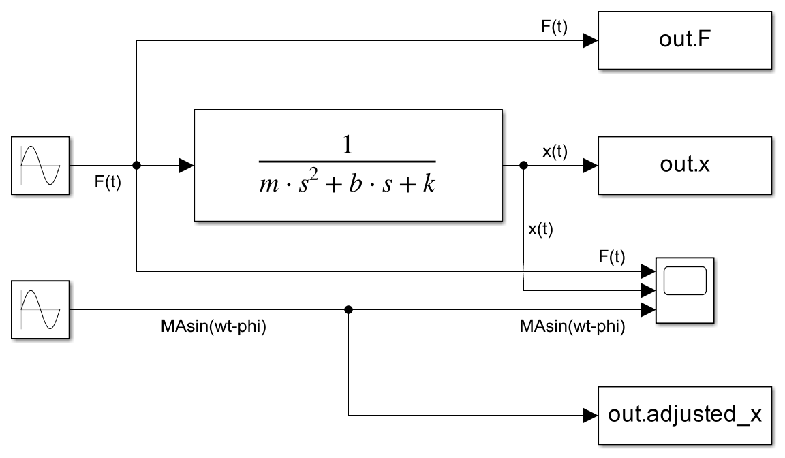

snapshotModel("ME322_Exercise_1_Simulink");

**Figure 4:** Block Diagram for the parallel mass-spring-damper system in Simulink

## Plots

*By the time you reach this course you should be familiar with all the features that a plot should have to be acceptable in a technical document. At the minimum follow the rules below. *

*• All plots must have a figure caption immediately following the figure. In some cases it is challenging to format a caption as you desire in MATLAB™, so figure titles will be allowed as well. Generally you don’t want to have both a title and a caption unless they are both adding useful information and are not redundant. *

*• All axes must have labels including things like units and variable names. *

*• Any data plotted on common axes must have equivalent units. For example, you can plot two displacements on the same axes, but not a displacement and a velocity. If you need to plot multiple pieces of data with different units consider subplots, multiple overlaid y-axes, or even multiple figures. *

*• A set of axes with more than one piece of data must have a legend that distinguishes for the reader what is being plotted. *

*• You will need to produce plots showing that multiple different methods lead to the same solution. In such as case the data plotted will overlap to such a degree that you will not be able to tell apart the different pieces of data even with a good legend. In such a case the data should likely be plotted with markers instead of as a solid line. Refer to the MATLAB™ documentation on Line and Marker Appearance for details*

This section will plot the simulation results to show the motion of the mass with respect to time. 

### Exercise 1A

#### Plots 1 and 2 - Displacement versus Time and Velocity versus Time

*Breif description of code (Section Comment).*

This section graph two plots. The first plot will show the displacement of the mass as a function of time. The second plot will show the velocity of the mass as a function of time.

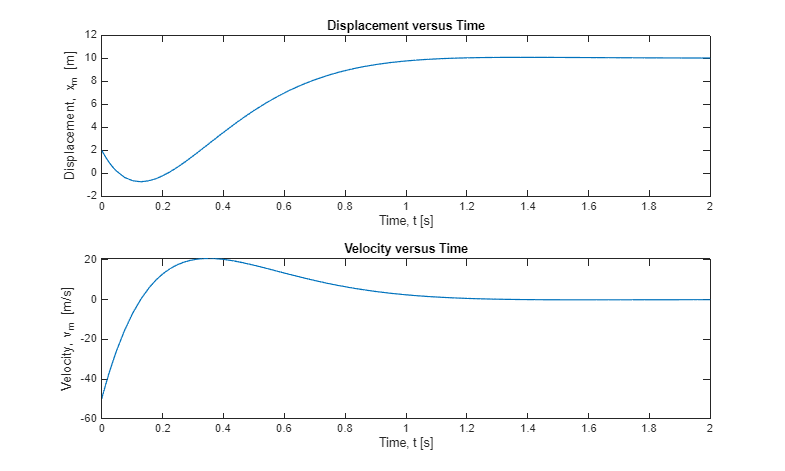

% Adjusting the size of the plot to be visible
figure('Position', [0 0 1000 600]); 
subplot(2,1,1);
    plot(tout, xout(:, 1), LineWidth=1);
    xlabel("Time, t [s]");
    ylabel("Displacement, x_m [m]");
    title("Displacement versus Time");
subplot(2,1,2);
    plot(tout, xout(:, 2), LineWidth=1);
    xlabel("Time, t [s]");
    ylabel("Velocity, v_m [m/s]");
    title("Velocity versus Time");

**Figure 5:** Displacement, $x_m$ versus Time, $t$ and Velocity, $v_m$ versus Time, $t$ from $0\le t\le 2$ for the parallel mass-spring-damper system

### Exercise 1B

#### Plot 3 and 4 - Force versus Time and Displacement versus Time

*Breif description of code (Section Comment).*

This section graph two plots. The first plot will show the forcing function as a function of time. The second plot will show the displacement of the mass as a function of time calculated through Simulink and through adjusting the input steady-state sinusoidal input by the magnitude ratio and phase shift calculated in Analysis - Exercise 1B section.

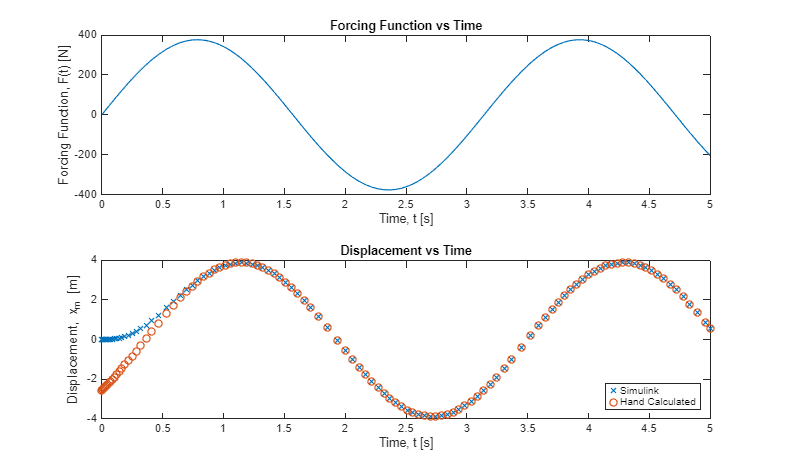

figure('Position', [0 0 1000 600]);
tiledlayout("vertical");
nexttile;
    plot(simout.tout, simout.F, LineWidth=1);
    xlabel("Time, t [s]");
    ylabel("Forcing Function, F(t) [N]");
    title("Forcing Function vs Time");
nexttile;
    plot(simout.tout, simout.x, "x", DisplayName ="Simulink", LineWidth=1);
    xlabel("Time, t [s]");
    ylabel("Displacement, x_m [m]");
    title("Displacement vs Time");
    hold on 
    plot(simout.tout, simout.adjusted_x, "o", DisplayName ="Hand Calculated", LineWidth=1);
    hold off
    legend(Location="southeast");

**Figure 6:** Forcing Function, $F\left(t\right)$ versus Time, $t$, and Displacement, $x_m$ versus Time, $t$ from $0\le t\le 5$ for the parallel mass-spring-damper system. The displacement graph consists of Simulink simulation and hand calculation repsonses. 

## Discussion Questions

*All discussion questions must be grouped together in a single section of the finished report. It should be abundantly clear which question goes with which answer. It is also a good idea to repeat the question in the body of the report before the answer*

### Exercise 1A

#### Question 1

*Suppose we had a third-order system, still in the dependent variable xm. What would be a valid choice of state variables for such a system? Provide a specific set of state variables along with a description of each variable.* 

#### Question 2

*For this system, the input F(t) is treated as a step input. That is, the input “turns on” at time zero, but has a value of zero for negative time. This is easy to handle in the ODE function because the simulation starts at time zero, so the input is effectively constant during the simulation time. *

*Suppose we wanted simulate the system response starting at t = 0 but we also want to delay the input by one second so that the input “turns on” at t =1 instead of at t = 0. How would you adjust your ODE function to account for this one second delay? *

*Do not actually modify your function file to implement the delay in the step input. However,consider using an example code snippet to supplement your answer to this question. You can insert example code using the “Insert” tab in the live editor so that it will format as text in your report submission without MATLAB™ trying to run the code in your example*

#### Question 3

*For this system, there are two ways energy can be stored - in potential energy or kinetic energy. The system also dissipates energy over time, as illustrated by the exponential decay visible in your plot.*

*Identify which parts of the model store energy and what type of energy they each store; additionally, determine which state variables are associated with each type of energy storage. Also identify which parts of the model dissipate energy. *

*Is it a coincidence that the number of state variables matches the number of different ways energy can be stored in the system?*

### Exercise 1B

#### Question 1

*Specifically, what does the simulation output represent? Is the simulation output in the time domain or the frequency/Laplace domain?* 

#### Question 2

*The denominator of the transfer function is a polynomial describing the fundamental dynamics associated with the system. *

*(a) What is the formal name for this polynomial? *

*(b) What information can you find from the roots of this polynomial? *

*(c) If you know the amplitude and frequency of the forcing function, what else can you find from the roots of the polynomial?* 

#### Question 3

*How could you modify the numerator of the transfer function to produce the derivative of the system output? What expression would you enter into the transfer function block parameters to select this new numerator?* 

#### Question 4

*The initial conditions specified in the background of the assignment are both zero. Is it possible to use a transfer function representation to consider systems with non-zero initial conditions? *

#### Question 5

*For the second-order system in this assignment, is there a driving frequency ω, that would result in a 180◦ phase shift? If it is possible, determine the value of ω that would cause such a phase shift; if it is not possible, explain why it is not possible and consider if other systems of different order could reach such a phase shift.* 

## Functions

*Breif description of code (Section Comment).*

### Mass-Spring-Damper Equations of Motion

The MBK_state_eqns is a function designed for use with "ode45". The function models the ODE for a mass-spring-damper system consisting of a second-order ordinary differential equation. To be used with MATLAB's "ode45" its inputs include a time variable, $t$, and a state vector $x$, in which the output is the differentiation of the state vector, $\dot{x}$. The state vector is a matrix with $n-1$ rows for a $n$th order ordinary differential equation in which each row is equal to the dirivative of the last. 

**Original ODE:**


$${\ddot{x} }_m =\frac{1}{m}\left(F\left(t\right)-b{\dot{x} }_m -kx_m \right)$$


**State Vector:**


$$\begin{array}{l}
x=\left\lbrack \begin{array}{c}
x_m \\
{\dot{x} }_m 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack \\
\dot{x} =\left\lbrack \begin{array}{c}
x_2 \\
\frac{1}{m}\left(F\left(t\right)-bx_2 -kx_1 \right)
\end{array}\right\rbrack 
\end{array}$$


function [xd] = MBK_state_eqns(t, x)
m = 4;     % [kg]    mass 
b = 32;    % [N*s/m] damping constant
k = 89;    % [N/m]   spring constant
F = 890;   % [N]     forcing function

% Differential equation
xd = [ x(2)                   % [m/s]   x_md  (v_m)
       (F-b*x(2)-k*x(1))/m ]; % [m/s^2] x_mdd (a_m)
end